# Image Category

## Load Images Dataset Folder

imgDs = imageDatastore('C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET', ...
    'FileExtensions', {'.jpg', '.png'}, ...
    'IncludeSubfolders',true, ...
    'LabelSource',"foldernames")

imgDs =   ImageDatastore with properties:

                       Files: {
                              ' ...\barbecued_red-ThaiFoodDataset-001.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-002.jpg';
                              ' ...\barbecued_red-ThaiFoodDataset-003.jpg'
                               ... and 12379 more
                              }
                     Folders: {
                              ' ...\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET'
                              }
                      Labels: [barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice; barbecued_red_pork_in_sauce_with_rice ... and 12379 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
     

## Dataset Analysis

### Show some sample Steak image

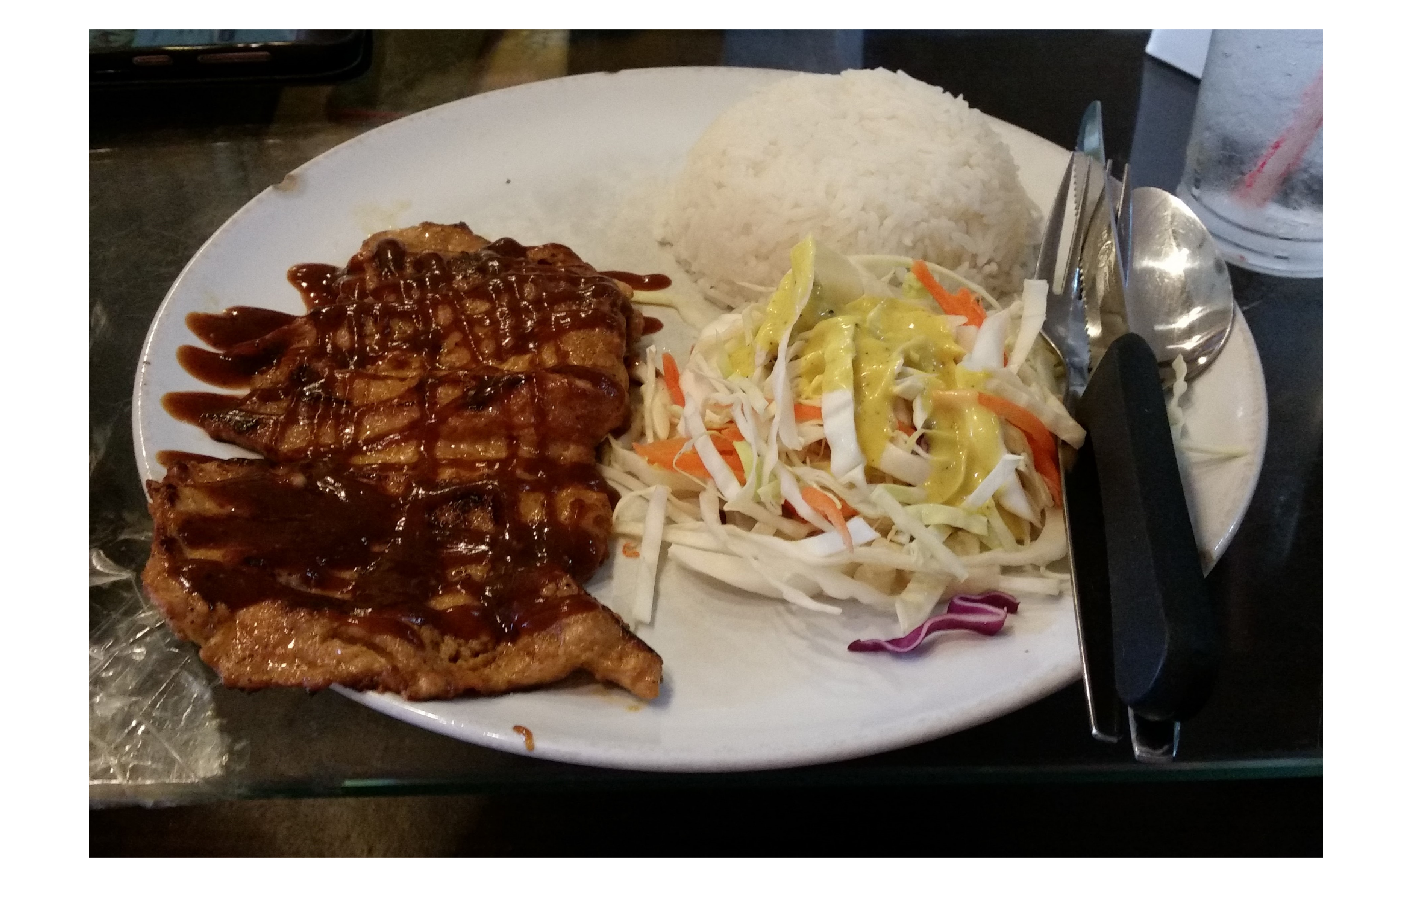

steak = find(imgDs.Labels == 'steak', 1);
        
figure
imshow(readimage(imgDs,steak))

### Count the number of data for each class

tbl = countEachLabel(imgDs)

tbl = 38×2 table
                    Label                     Count
    ______________________________________    _____

    barbecued_red_pork_in_sauce_with_rice      478 
    caesar_salad                               295 
    charcoal-boiled_pork_neck                  115 
    chow_mein                                  116 
    coconut_milk_soup                          111 
    crispy_pork_with_kale_with_rice            452 
    fried_chicken_with_rice                    347 
    fried_mussel_pancakes                      104 
    fried_pork_with_rice                       429 
    fried_rice                                1921 
    green_curry                                100 
    hamburger                                  267 
    hot_and_sour_fish_and_vegetable_ragout     113 
    kebab                                      251 
    khao_soi                                   118 
    noodles                   

classTypes = tbl{:,1}

classTypes = 38×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     caesar_salad 
     charcoal-boiled_pork_neck 
     chow_mein 
     coconut_milk_soup 
     crispy_pork_with_kale_with_rice 
     fried_chicken_with_rice 
     fried_mussel_pancakes 
     fried_pork_with_rice 
     fried_rice 
     green_curry 
     hamburger 
     hot_and_sour_fish_and_vegetable_ragout 
     kebab 
     khao_soi 
     noodles 
     noodles_with_fish_curry 
     noodles_without_soup 
     omelette 
     onion_rings 
     pad_see_ew 
     pad_thai 
     peking_duck 
     pizza 
     rice_crispy_pork 
     rice_topped_with_stir_fried_meat_and_basil 
     spaghetti_bolognese 
     spaghetti_carbonara 
     spicy_chicken_salad_with_rice 
     spicy_stir_fried_pork_with_red_curry_paste 


## Split the dataset for both training and testing set

[trainingSet, testSet] = splitEachLabel(imgDs, 0.7, 'randomize');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Show the size and the files of the training set
size(trainingSet.Files)

ans =         8670           1


trainingSet.Files

ans = 8670×1 cell array
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-001.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-002.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-003.jpg'}
    {'C:\Users\rektplorer64\OneDrive\Documents\MUICT Works\YEAR 4\ITCS476 - Digital Image Processing\Project 1 - Thai Food Image Recognition\datasets\FINAL DATASET\barbecued_red_pork_in_sauce_with_rice\barbecued_red-ThaiFoodDataset-005.jpg'}
    {'C:

# **Classifier Evaluation**

## METHOD 1: FEATURE MATCHING

### Train the training dataset to an Excel file!

evaluationExcelFilePath = './evaluate/eval_feature_matching_model.xlsx';
portion = 100

portion = 100


totalFiles = size(trainingSet.Files) - 1

totalFiles =         8669           0


progression = 0;
for i = 1 : portion : totalFiles
    
    T = table();
    
    for j = 0 : min(portion - 1, totalFiles - i)
       
        [filepath,name,ext] = fileparts(trainingSet.Files{i + j, 1});
        paths = split(filepath, '\');
        className = cell2mat(paths(end));
        % trainAnImage(evaluationExcelFilePath, readimage(imgDs, i), trainingSet.Files{i, 1}, className);
    
        [meanRed, meanGreen, meanBlue, meanGrayscale, bwArea, entropyVal, energy, contrast, correlation, homogeneity, sobelArea, cannyArea] = extractFeaturesFromAnImage(readimage(imgDs, i + j));

        path = convertCharsToStrings(trainingSet.Files{i + j, 1});
        class = {className};
        newTableRow = table(path, class, meanRed, meanGreen, meanBlue, meanGrayscale, bwArea, entropyVal, energy, contrast, correlation, homogeneity, sobelArea, cannyArea);
        T = [T; newTableRow];
        
        progression = progression + 1;
        
        if progression >= totalFiles
            break
        end
    end
    
    [string(progression) '/' string(totalFiles)] 
    % featureArray = [path className meanRed meanGreen meanBlue meanGrayscale bwArea entropyVal energy contrast correlation homogeneity sobelArea cannyArea]
    writetable(T, evaluationExcelFilePath, 'WriteMode', 'Append', 'WriteVariableNames',i == 1,'WriteRowNames',false);
end

ans = 1×4 string array
    "100"    "/"    "8669"    "0"


ans = 1×4 string array
    "200"    "/"    "8669"    "0"


ans = 1×4 string array
    "300"    "/"    "8669"    "0"


ans = 1×4 string array
    "400"    "/"    "8669"    "0"


ans = 1×4 string array
    "500"    "/"    "8669"    "0"


ans = 1×4 string array
    "600"    "/"    "8669"    "0"


ans = 1×4 string array
    "700"    "/"    "8669"    "0"


ans = 1×4 string array
    "800"    "/"    "8669"    "0"


ans = 1×4 string array
    "900"    "/"    "8669"    "0"


ans = 1×4 string array
    "1000"    "/"    "8669"    "0"


ans = 1×4 string array
    "1100"    "/"    "8669"    "0"


ans = 1×4 string array
    "1200"    "/"    "8669"    "0"


ans = 1×4 string array
    "1300"    "/"    "8669"    "0"


ans = 1×4 string array
    "1400"    "/"    "8669"    "0"


ans = 1×4 string array
    "1500"    "/"    "8669"    "0"


ans = 1×4 string array
    "1600"    "/"    "8669"    "0"


ans = 1×4 string array
    "1700"    "/"    "8669"    "0"


ans = 1×4 string array
    "1800"    "/"    "8669"    "0"


ans = 1×4 string array
    "1900"    "/"    "8669"    "0"


ans = 1×4 string array
    "2000"    "/"    "8669"    "0"


ans = 1×4 string array
    "2100"    "/"    "8669"    "0"


ans = 1×4 string array
    "2200"    "/"    "8669"    "0"


ans = 1×4 string array
    "2300"    "/"    "8669"    "0"


ans = 1×4 string array
    "2400"    "/"    "8669"    "0"


ans = 1×4 string array
    "2500"    "/"    "8669"    "0"


ans = 1×4 string array
    "2600"    "/"    "8669"    "0"


ans = 1×4 string array
    "2700"    "/"    "8669"    "0"


ans = 1×4 string array
    "2800"    "/"    "8669"    "0"


ans = 1×4 string array
    "2900"    "/"    "8669"    "0"


ans = 1×4 string array
    "3000"    "/"    "8669"    "0"


ans = 1×4 string array
    "3100"    "/"    "8669"    "0"


ans = 1×4 string array
    "3200"    "/"    "8669"    "0"


ans = 1×4 string array
    "3300"    "/"    "8669"    "0"


ans = 1×4 string array
    "3400"    "/"    "8669"    "0"


ans = 1×4 string array
    "3500"    "/"    "8669"    "0"


ans = 1×4 string array
    "3600"    "/"    "8669"    "0"


ans = 1×4 string array
    "3700"    "/"    "8669"    "0"


ans = 1×4 string array
    "3800"    "/"    "8669"    "0"


ans = 1×4 string array
    "3900"    "/"    "8669"    "0"


ans = 1×4 string array
    "4000"    "/"    "8669"    "0"


ans = 1×4 string array
    "4100"    "/"    "8669"    "0"


ans = 1×4 string array
    "4200"    "/"    "8669"    "0"


ans = 1×4 string array
    "4300"    "/"    "8669"    "0"


ans = 1×4 string array
    "4400"    "/"    "8669"    "0"


ans = 1×4 string array
    "4500"    "/"    "8669"    "0"


ans = 1×4 string array
    "4600"    "/"    "8669"    "0"


ans = 1×4 string array
    "4700"    "/"    "8669"    "0"


ans = 1×4 string array
    "4800"    "/"    "8669"    "0"


ans = 1×4 string array
    "4900"    "/"    "8669"    "0"


ans = 1×4 string array
    "5000"    "/"    "8669"    "0"


ans = 1×4 string array
    "5100"    "/"    "8669"    "0"


ans = 1×4 string array
    "5200"    "/"    "8669"    "0"


ans = 1×4 string array
    "5300"    "/"    "8669"    "0"


ans = 1×4 string array
    "5400"    "/"    "8669"    "0"


ans = 1×4 string array
    "5500"    "/"    "8669"    "0"


ans = 1×4 string array
    "5600"    "/"    "8669"    "0"


ans = 1×4 string array
    "5700"    "/"    "8669"    "0"


ans = 1×4 string array
    "5800"    "/"    "8669"    "0"


ans = 1×4 string array
    "5900"    "/"    "8669"    "0"


ans = 1×4 string array
    "6000"    "/"    "8669"    "0"


ans = 1×4 string array
    "6100"    "/"    "8669"    "0"


ans = 1×4 string array
    "6200"    "/"    "8669"    "0"


ans = 1×4 string array
    "6300"    "/"    "8669"    "0"


ans = 1×4 string array
    "6400"    "/"    "8669"    "0"


ans = 1×4 string array
    "6500"    "/"    "8669"    "0"


ans = 1×4 string array
    "6600"    "/"    "8669"    "0"


ans = 1×4 string array
    "6700"    "/"    "8669"    "0"


ans = 1×4 string array
    "6800"    "/"    "8669"    "0"


ans = 1×4 string array
    "6900"    "/"    "8669"    "0"


ans = 1×4 string array
    "7000"    "/"    "8669"    "0"


ans = 1×4 string array
    "7100"    "/"    "8669"    "0"


ans = 1×4 string array
    "7200"    "/"    "8669"    "0"


ans = 1×4 string array
    "7300"    "/"    "8669"    "0"


ans = 1×4 string array
    "7400"    "/"    "8669"    "0"


ans = 1×4 string array
    "7500"    "/"    "8669"    "0"


ans = 1×4 string array
    "7600"    "/"    "8669"    "0"


ans = 1×4 string array
    "7700"    "/"    "8669"    "0"


ans = 1×4 string array
    "7800"    "/"    "8669"    "0"


ans = 1×4 string array
    "7900"    "/"    "8669"    "0"


ans = 1×4 string array
    "8000"    "/"    "8669"    "0"


ans = 1×4 string array
    "8100"    "/"    "8669"    "0"


ans = 1×4 string array
    "8200"    "/"    "8669"    "0"


ans = 1×4 string array
    "8300"    "/"    "8669"    "0"


ans = 1×4 string array
    "8400"    "/"    "8669"    "0"


ans = 1×4 string array
    "8500"    "/"    "8669"    "0"


ans = 1×4 string array
    "8600"    "/"    "8669"    "0"


ans = 1×4 string array
    "8669"    "/"    "8669"    "0"


### Test the classifier by iterating thru each testing example and predict some food

excelTable = readtable('./evaluate/eval_feature_matching_model.xlsx');
table2array(excelTable(:, 1));

predictedLabels = [];
for z = 1:size(testSet.Files)
    image = imread(testSet.Files{z, 1});
    [matchingImagePath, distance, className] = recogizeByFeatures(evaluationExcelFilePath, image);
    
    predictedLabels = [predictedLabels; className];
end


### EVALUATE & SUMMARY

testPrediction = categorical(predictedLabels)

testPrediction = 3712×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_w

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, testPrediction)

confMat = 10×30
    97    46     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    18    27    21    22     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     5    29     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    35     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    29     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    70    21    45     0     0     0     0 


% Convert confusion matrix into percentage form
percentConfMat = bsxfun(@rdivide,confMat,sum(confMat,2))

percentConfMat = 10×30
    0.6783    0.3217         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.2045    0.3068    0.2386    0.2500         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1471    0.8529         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0    

averageAccuracy = mean(diag(percentConfMat))

averageAccuracy = 0.0431


% Find the precision
for i = 1:size(confMat,1)
    precision(i) = confMat(i,i) / sum(confMat(i, :));
end

% Find the recall
for i = 1:size(confMat,1)
    recall(i) = confMat(i,i) / sum(confMat(:, i));
end
precision

precision = 1×30
    0.6783    0.2045         0         0         0         0         0         0    0.0155    0.3229         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0101    0.0571         0    0.0267         0    0.0182


recall

recall = 1×30
    0.6062    0.1818         0         0         0         0         0         0    0.0146    0.3438         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0104    0.0593         0    0.0400         0    0.0208



% Find the F1 SCORE
f1Score = (2 .* precision .* recall) ./ (precision + recall)

f1Score = 1×30
    0.6403    0.1925       NaN       NaN       NaN       NaN       NaN       NaN    0.0150    0.3330       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.0103    0.0582       NaN    0.0320       NaN    0.0194



summaryA = table(classTypes, precision', recall', f1Score')

summaryA = 38×4 table
                  classTypes                    Var2        Var3        Var4  
    ______________________________________    ________    ________    ________

    barbecued_red_pork_in_sauce_with_rice      0.67832     0.60625     0.64026
    caesar_salad                               0.20455     0.18182     0.19251
    charcoal-boiled_pork_neck                        0           0         NaN
    chow_mein                                        0           0         NaN
    coconut_milk_soup                                0           0         NaN
    crispy_pork_with_kale_with_rice                  0           0         NaN
    fried_chicken_with_rice                          0           0         NaN
    fried_mussel_pancakes                            0           0         NaN
    fried_pork_with_rice                      0.015

## METHOD 2: DEEP LEARNING + SVM

### Train the training dataset

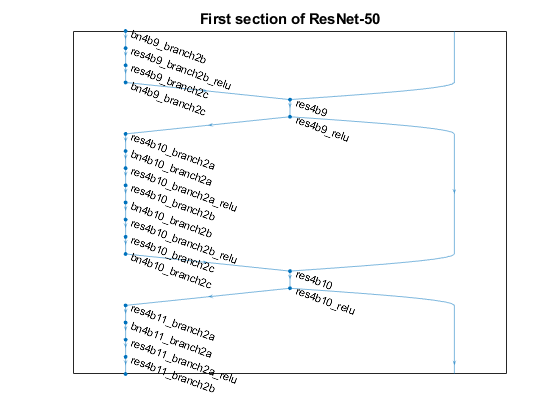



net = resnet101();

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);


net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_predictions'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


numel(net.Layers(end).ClassNames)

ans = 1000

## Preparing Training and Testing set

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize

imageSize =    224   224     3


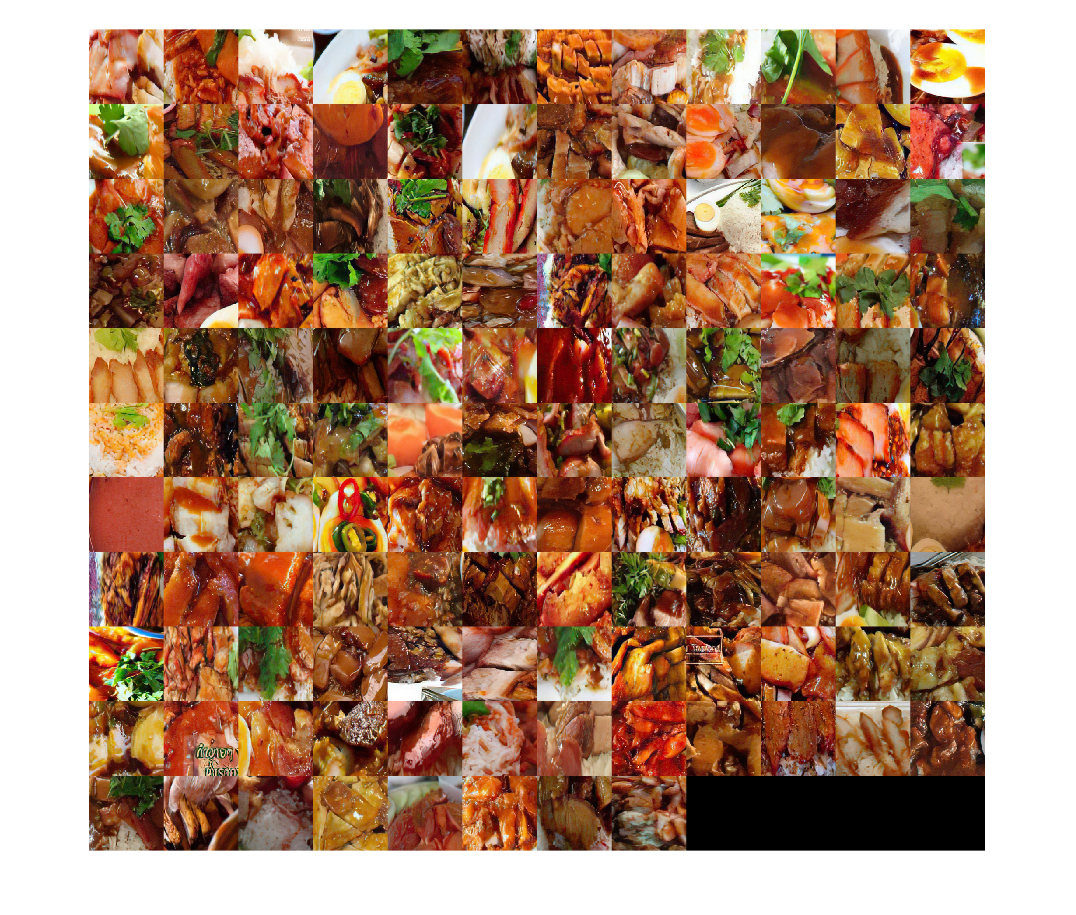


trainingSet.ReadFcn = @scaleimage;
testSet.ReadFcn = @scaleimage;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, "OutputSizeMode", "centercrop");
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, "OutputSizeMode", "centercrop" );

minibatch = read(augmentedTrainingSet);
imshow(imtile(minibatch.input))

%% Get the activation of the last fully-connected layer
featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels

trainingLabels = 8670×1 categorical array
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_with_rice 
     barbecued_red_pork_in_sauce_w


% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.

classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');


% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels)

confMat =     82     0     0     0     0     1     5     1     0     0     0     1     0     0     0     0     0     1     8     0    10     0     0     0     7     6     1     0     0    16     0     0     0     2     0     0     0     2
     0    57     0     0     0     0     0     4     0     1     7     5     0     0     0     1     0     0     4     1     0     0     0     0     0     2     2     1     0     0     0     1     0     0     1     1     0     0
     0     0    24     1     0     0     1     4     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     1     0
     0     0     0    30     0     0     0     3     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     0    18     0     0     2     0     0    10     0  


% Convert confusion matrix into percentage form
percentConfMat = bsxfun(@rdivide,confMat,sum(confMat,2))

percentConfMat =     0.5734         0         0         0         0    0.0070    0.0350    0.0070         0         0         0    0.0070         0         0         0         0         0    0.0070    0.0559         0    0.0699         0         0         0    0.0490    0.0420    0.0070         0         0    0.1119         0         0         0    0.0140         0         0         0    0.0140
         0    0.6477         0         0         0         0         0    0.0455         0    0.0114    0.0795    0.0568         0         0         0    0.0114         0         0    0.0455    0.0114         0         0         0         0         0    0.0227    0.0227    0.0114         0         0         0    0.0114         0         0    0.0114    0.0114         0         0
         0         0    0.7059    0.0294         0         0    0.0294    0.1176         0         0         0         0         0         0         0         0         0         0         0    0.0294         0         0 

averageAccuracy = mean(diag(percentConfMat))

averageAccuracy = 0.6143


% Find the precision
for i = 1:size(confMat,1)
    precision(i) = confMat(i,i) / sum(confMat(i, :));
end

% Find the recall
for i = 1:size(confMat,1)
    recall(i) = confMat(i,i) / sum(confMat(:, i));
end
precision

precision =     0.5734    0.6477    0.7059    0.8571    0.5455    0.6691    0.3942    0.7742    0.3101    0.7396    0.8000    0.7000    0.6765    0.9467    0.7143    0.0839    0.2333    0.1864    0.8270    0.9200    0.8020    0.4156    0.5263    0.8333    0.1919    0.4500    0.7067    0.7867    0.4000    0.8000    0.6800    0.6854    0.7500    0.7033    0.8710    0.5938    0.6757    0.1667


recall

recall =     0.4316    0.7808    0.7500    0.6122    0.6667    0.7339    0.3628    0.1805    0.7547    0.7904    0.2927    0.6914    0.7419    0.9861    0.7576    0.5909    0.5385    0.4648    0.5985    0.8415    0.3716    0.8000    0.8696    0.9420    0.4130    0.4599    0.7465    0.8082    0.5000    0.2211    0.9623    0.7439    0.6667    0.8258    0.8710    0.7600    0.7813    0.4286



% Find the F1 SCORE
f1Score = (2 .* precision .* recall) ./ (precision + recall)

f1Score =     0.4925    0.7081    0.7273    0.7143    0.6000    0.7000    0.3779    0.2927    0.4396    0.7641    0.4286    0.6957    0.7077    0.9660    0.7353    0.1469    0.3256    0.2661    0.6944    0.8790    0.5078    0.5470    0.6557    0.8844    0.2621    0.4549    0.7260    0.7973    0.4444    0.3465    0.7969    0.7135    0.7059    0.7597    0.8710    0.6667    0.7246    0.2400



summaryB = table(classTypes, precision', recall', f1Score')

summaryB = 38×4 table
                  classTypes                    Var2       Var3       Var4  
    ______________________________________    ________    _______    _______

    barbecued_red_pork_in_sauce_with_rice      0.57343    0.43158    0.49249
    caesar_salad                               0.64773    0.78082    0.70807
    charcoal-boiled_pork_neck                  0.70588       0.75    0.72727
    chow_mein                                  0.85714    0.61224    0.71429
    coconut_milk_soup                          0.54545    0.66667        0.6
    crispy_pork_with_kale_with_rice            0.66912    0.73387        0.7
    fried_chicken_with_rice                    0.39423    0.36283    0.37788
    fried_mussel_pancakes                      0.77419    0.18045    0.29268
    fried_pork_with_rice                       0.31008    0.75472    0.